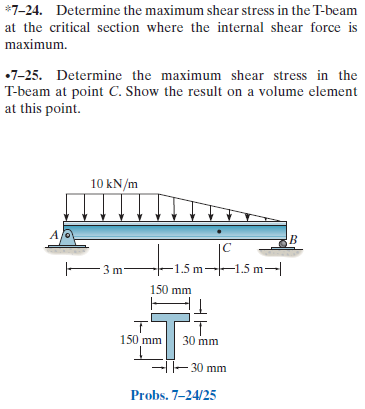

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-24P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-24P-solution-9780136022305) (problem 7-24)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-25P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-25P-solution-9780136022305) (problem 7-25)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
w1(x) = -10*u.kN/u.m;
w2 = findpoly(1, 'thru', [3*u.m -10*u.kN/u.m], 'thru', [6*u.m 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 6*u.m);
b = b.add('distributed', 'force', w1, [0 3]*u.m);
b = b.add('distributed', 'force', w2, [3 6]*u.m, [false true]);
b.L = 6*u.m;

# section properties

yc = [150+30/2 150/2]*u.mm;
Ac = [150*30 30*150]*u.mm^2;
Ic = [150*30^3 30*150^3]/12*u.mm^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{125000\,x\,\left(10\,x^{3}-110\,x^{2}\,m+1827\,m^{3}\right)}{81\,\text{E}}\,\frac{\mathrm{kN}}{m^{5}} & \text{ if }x\leq 3\,m\\ \frac{125000\,\left(x-6\,m\right)\,\left(2\,x^{4}-48\,x^{3}\,m+222\,x^{2}\,m^{2}+792\,x\,m^{3}+81\,m^{4}\right)}{243\,\text{E}}\,\frac{\mathrm{kN}}{m^{6}} & \text{ if }3\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{125000\,\left(40\,x^{3}-330\,x^{2}\,m+1827\,m^{3}\right)}{81\,\text{E}}\,\frac{\mathrm{kN}}{m^{5}} & \text{ if }x\leq 3\,m\\ -\frac{125000\,\left(-10\,x^{4}+240\,x^{3}\,m-1530\,x^{2}\,m^{2}+1080\,x\,m^{3}+4671\,m^{4}\right)}{243\,\text{E}}\,\frac{\mathrm{kN}}{m^{6}} & \text{ if }3\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(2\,x-11\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ \frac{5\,\left(x-6\,m\right)\,\left(2\,x^{2}-24\,x\,m+9\,m^{2}\right)}{18}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(4\,x-11\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ \frac{5\,\left(2\,x^{2}-24\,x\,m+51\,m^{2}\right)}{6}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -10\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ \frac{10\,\left(x-6\,m\right)}{3}\,\frac{\mathrm{kN}}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 27.5\,\mathrm{kN}\\ \mathrm{Rb} & 17.5\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

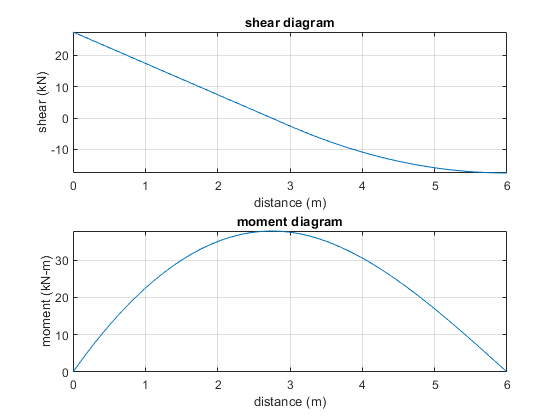

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# absolute maximum shear stress

V_max = v(0);
Q_max = (yn/2)*30*u.mm*yn;
b.I = rewrite(b.I, u.mm);
t_min = 30*u.mm;
tau_max_abs = rewrite(V_max*Q_max/(b.I*t_min), u.MPa);
tau_max_abs_vpa = vpa(tau_max_abs, 3) %#ok<NASGU> 

$$tau\_max\_abs\_vpa = 7.33\,\mathrm{MPa}$$

# maximum shear stress at point C

Vc = v(4.5*u.m);
tau_max_C = rewrite(-Vc*Q_max/(b.I*t_min), u.MPa);
tau_max_C_vpa = vpa(tau_max_C, 3) %#ok<NASGU> 

$$tau\_max\_C\_vpa = 3.67\,\mathrm{MPa}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear tau_max_abs_vpa;
clear tau_max_C_vpa;